# Surface integral term (mass matrix) and its lumping

For 2D elements, surface integral is done on a line. Let's calculate this on a reference line [0,1].

4 shape functions on this reference line are:


$$N_1=-\frac92(x-\frac13)(x-\frac23)(x-1)$$



$$N_2=\frac{27}{2}x(x-\frac23)(x-1)$$



$$N_3=-\frac{27}{2}x(x-\frac13)(x-1)$$



$$N_4=\frac92x(x-\frac13)(x-\frac23)$$


syms x N_1 N_2 N_3 N_4
N_1 = -9/2*(x-1/3)*(x-2/3)*(x-1)

$$N\_1 = -\left(\frac{9\,x}{2}-\frac{3}{2}\right)\,\left(x-1\right)\,\left(x-\frac{2}{3}\right)$$

N_2 = 27/2*x*(x-2/3)*(x-1)

$$N\_2 = \frac{27\,x\,\left(x-1\right)\,\left(x-\frac{2}{3}\right)}{2}$$

N_3 = -27/2*x*(x-1/3)*(x-1)

$$N\_3 = -\frac{27\,x\,\left(x-1\right)\,\left(x-\frac{1}{3}\right)}{2}$$

N_4 = 9/2*x*(x-1/3)*(x-2/3)

$$N\_4 = \frac{9\,x\,\left(x-\frac{1}{3}\right)\,\left(x-\frac{2}{3}\right)}{2}$$

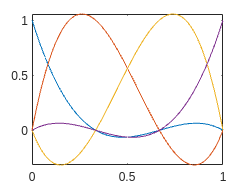

fplot(N_1,[0,1])
hold on
fplot(N_2,[0,1])
fplot(N_3,[0,1])
fplot(N_4,[0,1])

Mass matrix entry:


$$\int_0^1 N_i N_j\,dx$$


M(1,1) = int(N_1*N_1, x, 0,1);
M(1,2) = int(N_1*N_2, x, 0,1);
M(1,3) = int(N_1*N_3, x, 0,1);
M(1,4) = int(N_1*N_4, x, 0,1);
M(2,1) = int(N_2*N_1, x, 0,1);
M(2,2) = int(N_2*N_2, x, 0,1);
M(2,3) = int(N_2*N_3, x, 0,1);
M(2,4) = int(N_2*N_4, x, 0,1);
M(3,1) = int(N_3*N_1, x, 0,1);
M(3,2) = int(N_3*N_2, x, 0,1);
M(3,3) = int(N_3*N_3, x, 0,1);
M(3,4) = int(N_3*N_4, x, 0,1);
M(4,1) = int(N_4*N_1, x, 0,1);
M(4,2) = int(N_4*N_2, x, 0,1);
M(4,3) = int(N_4*N_3, x, 0,1);
M(4,4) = int(N_4*N_4, x, 0,1);

eval(M)

ans =     0.0762    0.0589   -0.0214    0.0113
    0.0589    0.3857   -0.0482   -0.0214
   -0.0214   -0.0482    0.3857    0.0589
    0.0113   -0.0214    0.0589    0.0762


sum(M)

$$ans = \left(\begin{array}{cccc} \frac{1}{8} & \frac{3}{8} & \frac{3}{8} & \frac{1}{8} \end{array}\right)$$